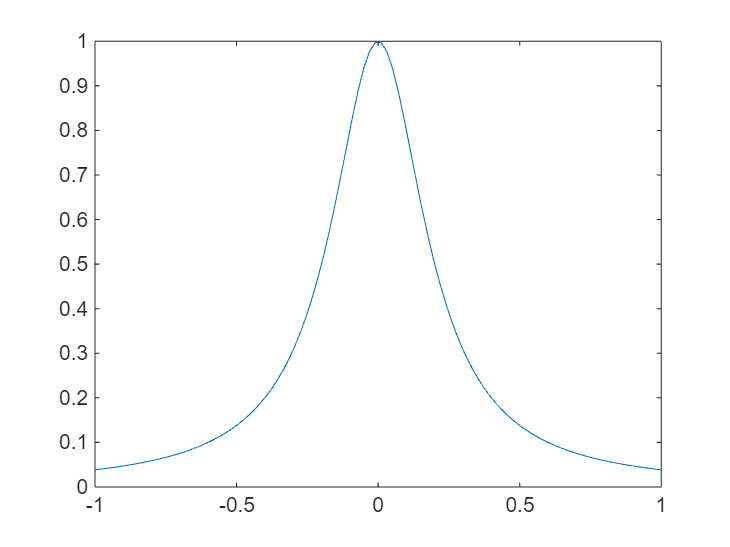

clear variables
close all

% define runge function
alpha = 25;
r = @(x) 1./(1+alpha*x.^2); % try sin(x)

% define grid
x = linspace(-1,1,100);
 
% plot runge function
plot(x,r(x))

Interpolate with a polynomial of degree 2, 4 and 6

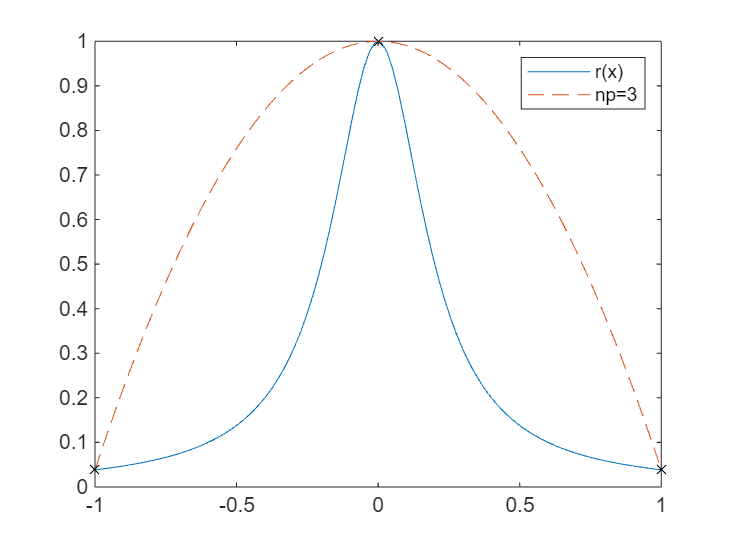

function polynterp(f,a,b,np)
    x_i = linspace(a,b,np); % define np evaluation points
    p = polyfit(x_i, f(x_i), np-1); % computes Langrange polinomials

    x = linspace(-1,1,100);

    plot(x,f(x),...
    x,polyval(p,x),'--',...
    x_i,f(x_i),'kx')
    legend('r(x)',strcat('np=',num2str(np)),'')
end

polynterp(r,-1,1,3) % three points for evaluation (polynomial of order 2)

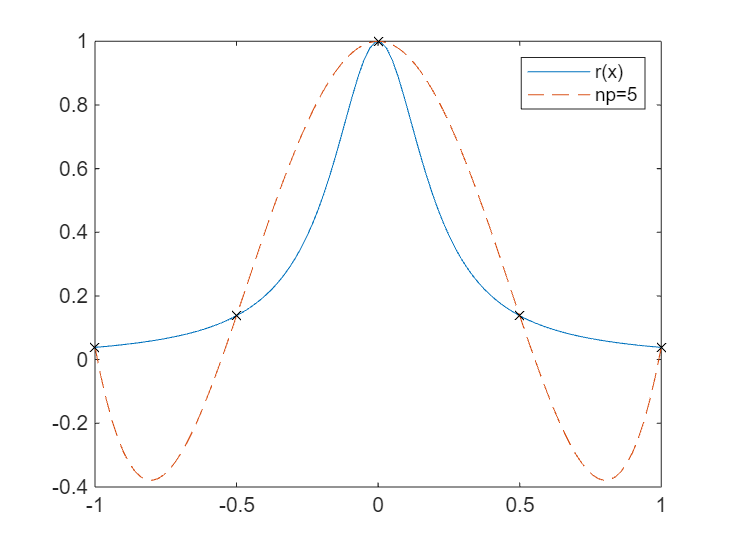

polynterp(r,-1,1,5) % 4-th order polynomial

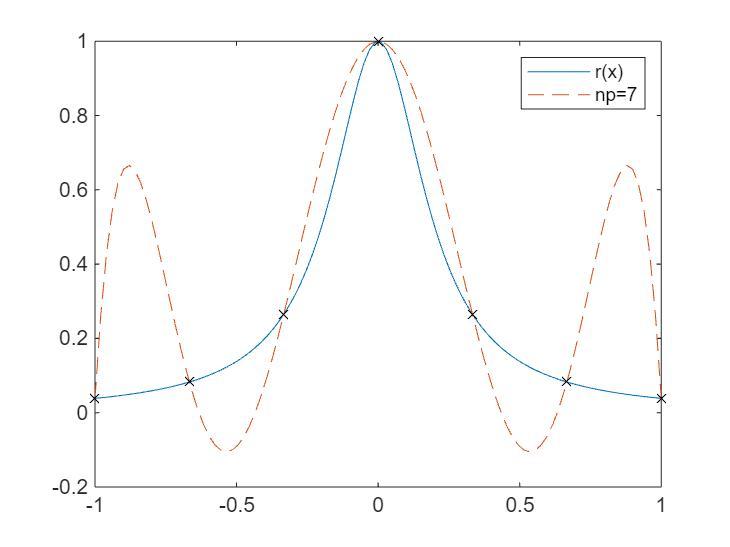

ans = 36.6667

ans = 36.6667

polynterp(r,-1,1,7) % 6-th order polynomial